# Actividad de cierre

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) l1 l2 l3 l4 h r t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4];

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Tomando en cuenta que para q1 nuestro marco de referencia se encuentra de la siguiente manera:

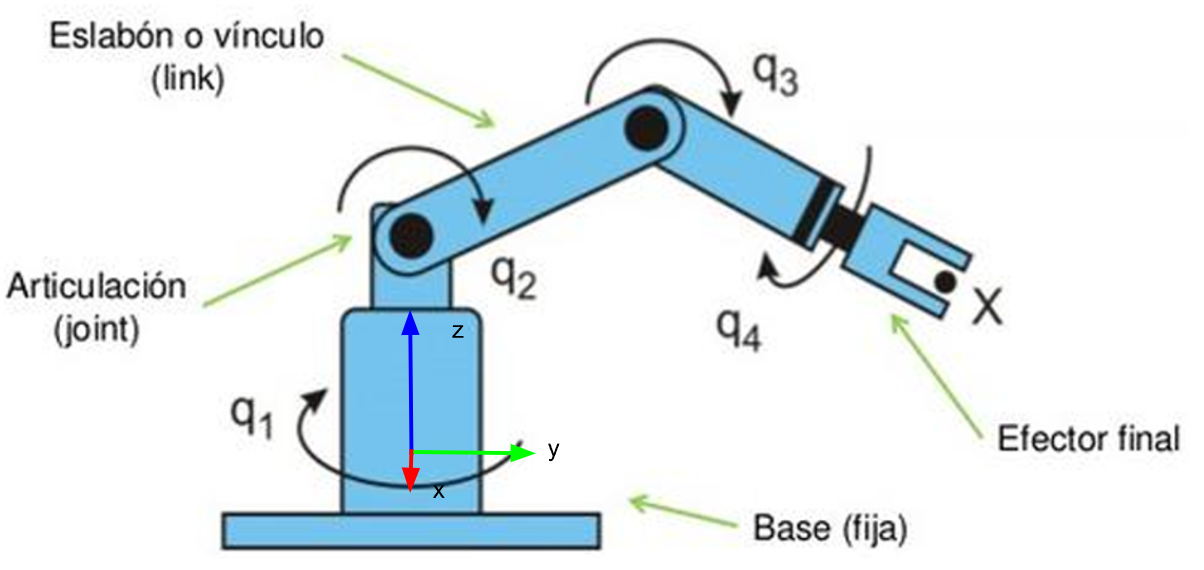

Con este marco de referencia podemos ver que necesitamos un giro de 90° en y, para la articulación 1.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0; h];
%Matriz de rotación de la junta 1 respecto a 0.... y
R(:,:,1)=       [cos(th1)   -sin(th1)   0;
                 sin(th1)    cos(th1)   0;
                 0          0           1] * [0 0  1;
                                              0 1  0;
                                              -1 0  0];

Para la articulación 2 no es necesario rotarla ya que se encuentra en la misma posición que la articulación 3.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*sin(th2); l2*cos(th2);0];
%Matriz de rotación de la junta 2 respecto a 1...z
    R(:,:,2)=   [cos(th2) -sin(th2)  0;
                 sin(th2)  cos(th2)  0;
                 0         0         1];

Por último para la articulación 3 rotamos -90° en x para alcanzar la posición de la articulación 4.

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*sin(th3); l3*cos(th3);0];
%Matriz de rotación de la junta 3 respecto a 2...x
R(:,:,3)=   [cos(th3) -sin(th3)  0;
             sin(th3)  cos(th3)  0;
              0        0         1] * [1 0 0;
                                       0 0 1;
                                       0 -1 0];
%Articulación 4
%Posición de la articulación 4 respecto a 3
P(:,:,4)= [r; r; l4];
%Matriz de rotación de la junta 4 respecto a 3  0º
R(:,:,4)=   [cos(th4) -sin(th4)  0;
             sin(th4)  cos(th4)  0;
              0         0         1];
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación global T1


/  0, -sin(th1(t)), cos(th1(t)), 0 \
|                                  |
|  0,  cos(th1(t)), sin(th1(t)), 0 |
|                                  |
| -1,       0,           0,      h |
|                                  |
\  0,       0,           0,      1 /



Matriz de Transformación global T2


/ -sin(th1(t)) sin(th2(t)), -cos(th2(t)) sin(th1(t)), cos(th1(t)), -l2 cos(th2(t)) sin(th1(t)) \
|                                                                                              |
|  cos(th1(t)) sin(th2(t)),  cos(th1(t)) cos(th2(t)), sin(th1(t)),  l2 cos(th1(t)) cos(th2(t)) |
|                                                                                              |
|       -cos(th2(t)),              sin(th2(t)),            0,           h - l2 sin(th2(t))     |
|                                                                                              |
\             0,                        0,                 0,                   1              /



Matriz de Transformación global T3


/ -sin(th1(t)) sin(#1), -cos(th1(t)), -sin(th1(t)) cos(#1),         -sin(th1(t)) #2         \
|                                                                                           |
|  cos(th1(t)) sin(#1), -sin(th1(t)),  cos(th1(t)) cos(#1),          cos(th1(t)) #2         |
|                                                                                           |
|       -cos(#1),             0,             sin(#1),       h - l2 sin(th2(t)) + l3 sin(#3) |
|                                                                                           |
\           0,                0,                0,                         1                /

where

   #1 == th2(t) + th3(t)

   #2 == l2 cos(th2(t)) + l3 cos(#3)

   #3 == th2(t) - th3(t)




Matriz de Transformación global T4


/ - cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#1),  sin(th1(t)) sin(th4(t)) sin(#1) - cos(th1(t)) cos(th4(t)),  -sin(th1(t)) cos(#1), - r cos(th1(t)) - sin(th1(t)) #2 - l4 sin(th1(t)) cos(#1) - r sin(th1(t)) sin(#1) \
|                                                                                                                                                                                                                                   |
|  cos(th1(t)) cos(th4(t)) sin(#1) - sin(th1(t)) sin(th4(t)),  - cos(th4(t)) sin(th1(t)) - cos(th1(t)) sin(th4(t)) sin(#1),  cos(th1(t)) cos(#1),  cos(th1(t)) #2 - r sin(th1(t)) + l4 cos(th1(t)) cos(#1) + r cos(th1(t)) sin(#1)  |
|                                                                                                                                                                                                                                   |
|                     -cos(th4(t)) cos(#1),                                     



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp')

%pretty(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp')

$$W(t) = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{3}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)-\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ \sigma_{4}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{3}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left(\sigma_{2}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}+\sigma_{1}\,\sin\left(\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)}\\ \sigma_{2}={\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\\ \sigma_{4}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)} \end{array}$$

%pretty(W);

## RESULTADOS: